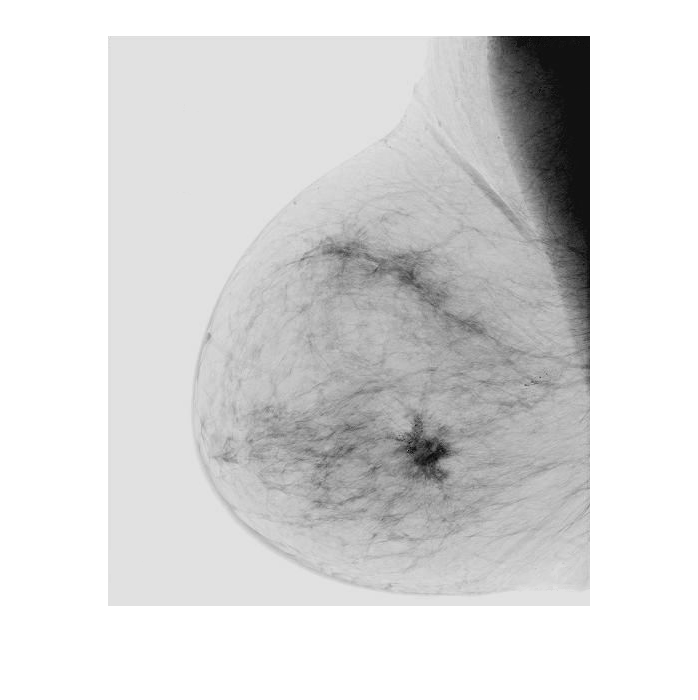

f = imread('breast.tif');
g1 = imadjust(f, [0 1], [1 0]);
g11 = imcomplement(f);
imshow(g1), figure, imshow(g11)

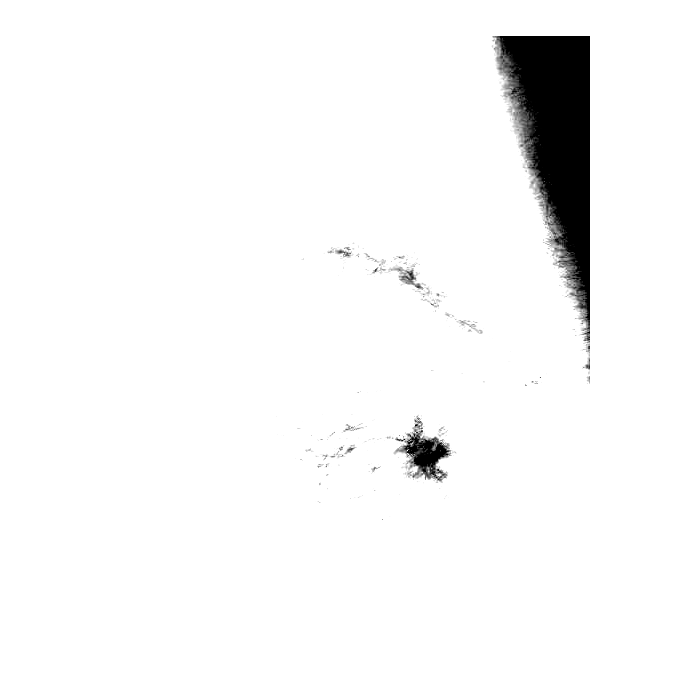

g2 = imadjust(f, [0.5 0.75], [1 0]);
g3 = imadjust(f, [], [], 2);
figure, imshow(g2);

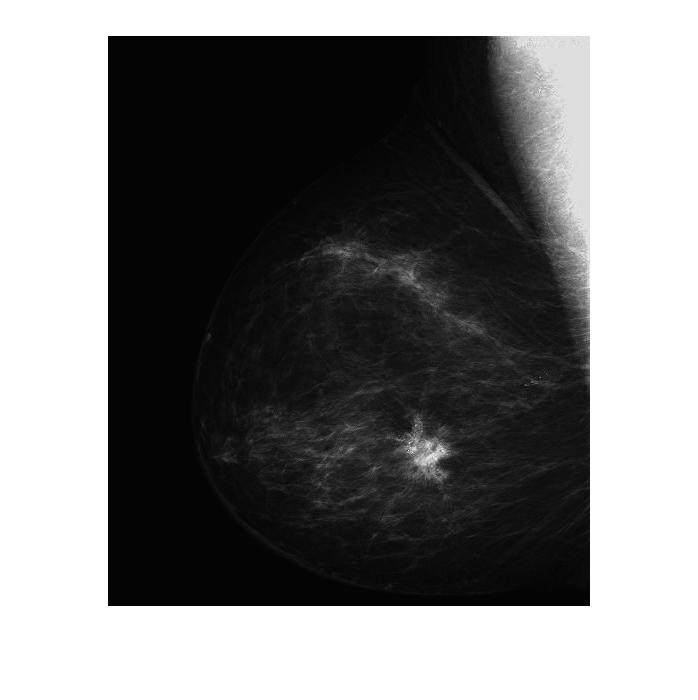

figure, imshow(g3);

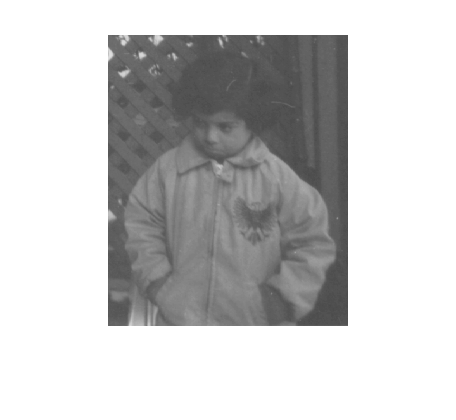

f = imread('pout.tif'); imshow(f);

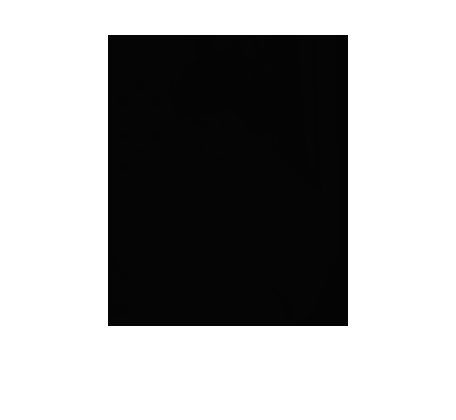

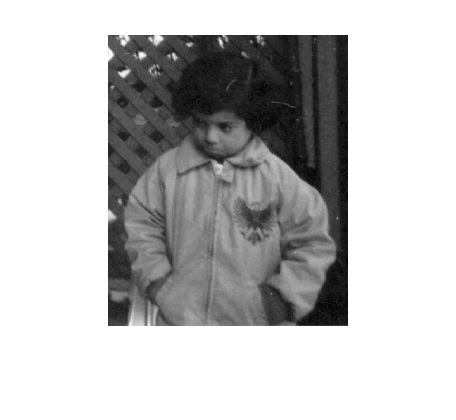

c = 1;
gc = c*log(1+double(f));
gc1 = im2uint8(mat2gray(gc)); % Decompress
figure, imshow(uint8(gc)), figure, imshow(gc1);

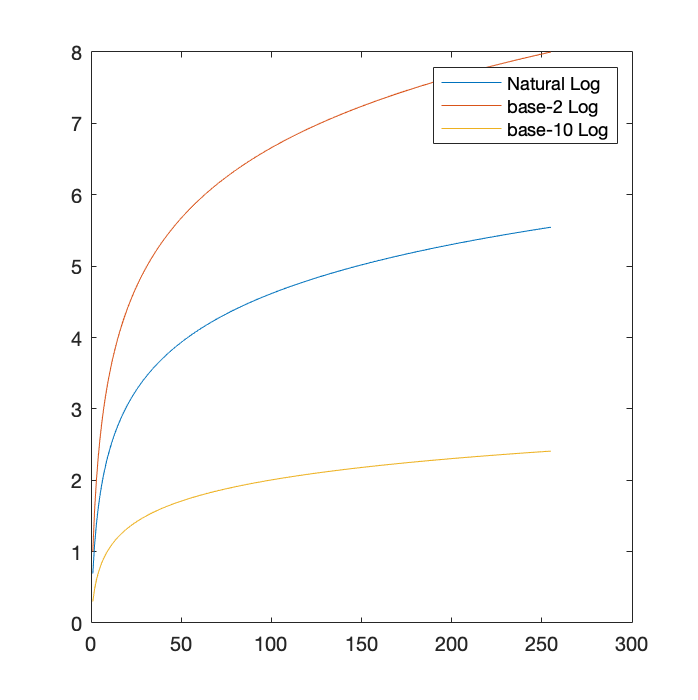

%%%% --- Logarithm Transformation ---
x = uint8(1:255);
c = 1;
gp1 = c*log(1+double(x));
gp2 = c*log2(1+double(x));
gp3 = c*log10(1+double(x));
figure(3);
plot(x,gp1,x,gp2,x,gp3);
legend('Natural Log', 'base-2 Log', 'base-10 Log');

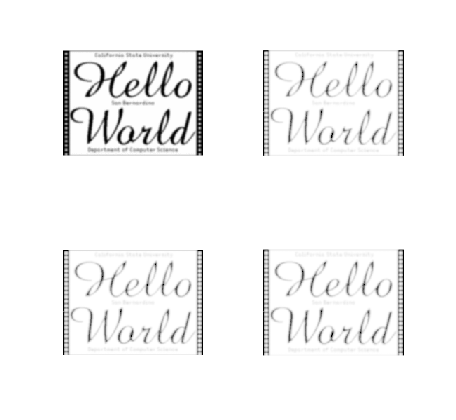


f = imread('blurimg.gif');
g1 = c*log(1+double(f));
gs1 = im2uint8(mat2gray(g1));
g2 = c*log2(1+double(f));
gs2 = im2uint8(mat2gray(g2));
g3 = c*log10(1+double(f));
gs3 = im2uint8(mat2gray(g3));

figure(4);
subplot(2,2,1); imshow(f);
subplot(2,2,2); imshow(gs1);
subplot(2,2,3); imshow(gs2);
subplot(2,2,4); imshow(gs3);

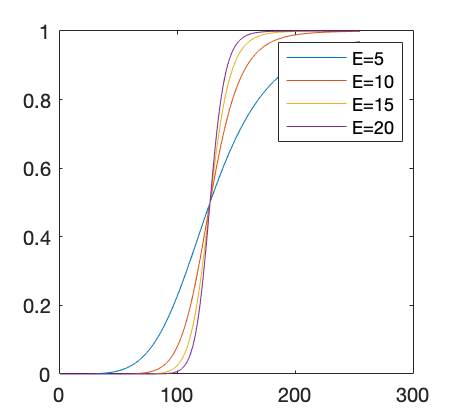

%%% --- Constrast-Stretching Transformation ---
% Plot Constrast-Stretching Graph
m = 150;
E = 15;
m = 128;
G1 = 1./(1+(m./(double(x)+eps)).^5);
G2 = 1./(1+(m./(double(x)+eps)).^10);
G3 = 1./(1+(m./(double(x)+eps)).^E);
G4 = 1./(1+(m./(double(x)+eps)).^20);
figure(5);
plot(x,G1,x,G2,x,G3,x,G4);
legend('E=5', 'E=10', 'E=15', 'E=20');

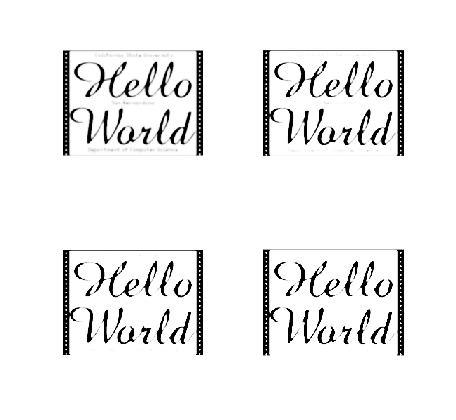

%%% --- Constrast-Stretching Transformation ---
% Plot Constrast-Stretching Image
G1 = 1./(1+((m)./(double(f)+eps)).^5);
G2 = 1./(1+(m./(double(f)+eps)).^10);
G3 = 1./(1+(m./(double(f)+eps)).^15);
G4 = 1./(1+(m./(double(f)+eps)).^20);

GS1 = im2uint8(mat2gray(G1));
GS2 = im2uint8(mat2gray(G2));
GS3 = im2uint8(mat2gray(G3));
GS4 = im2uint8(mat2gray(G4));

figure(6);
subplot(2,2,1); imshow(uint8(GS1));
subplot(2,2,2); imshow(uint8(GS2));
subplot(2,2,3); imshow(uint8(GS3));
subplot(2,2,4); imshow(uint8(GS4));

%%% --- Histogram ---
b = 256;
h = imhist(f, b);
p = imhist(f, b)/numel(f);
h, p

h =    365
     0
     0
     0
     0
   208
     0
     0
     0
     0


p =     0.0122
         0
         0
         0
         0
    0.0069
         0
         0
         0
         0


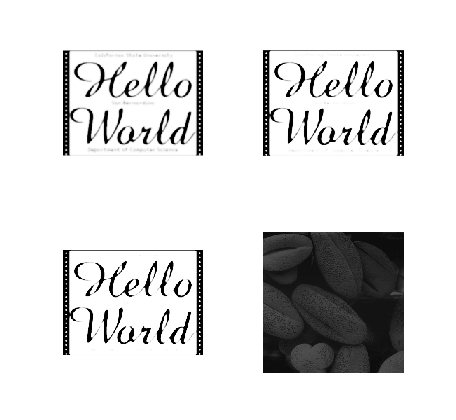

f = imread('pollen.tif');
imshow(f);

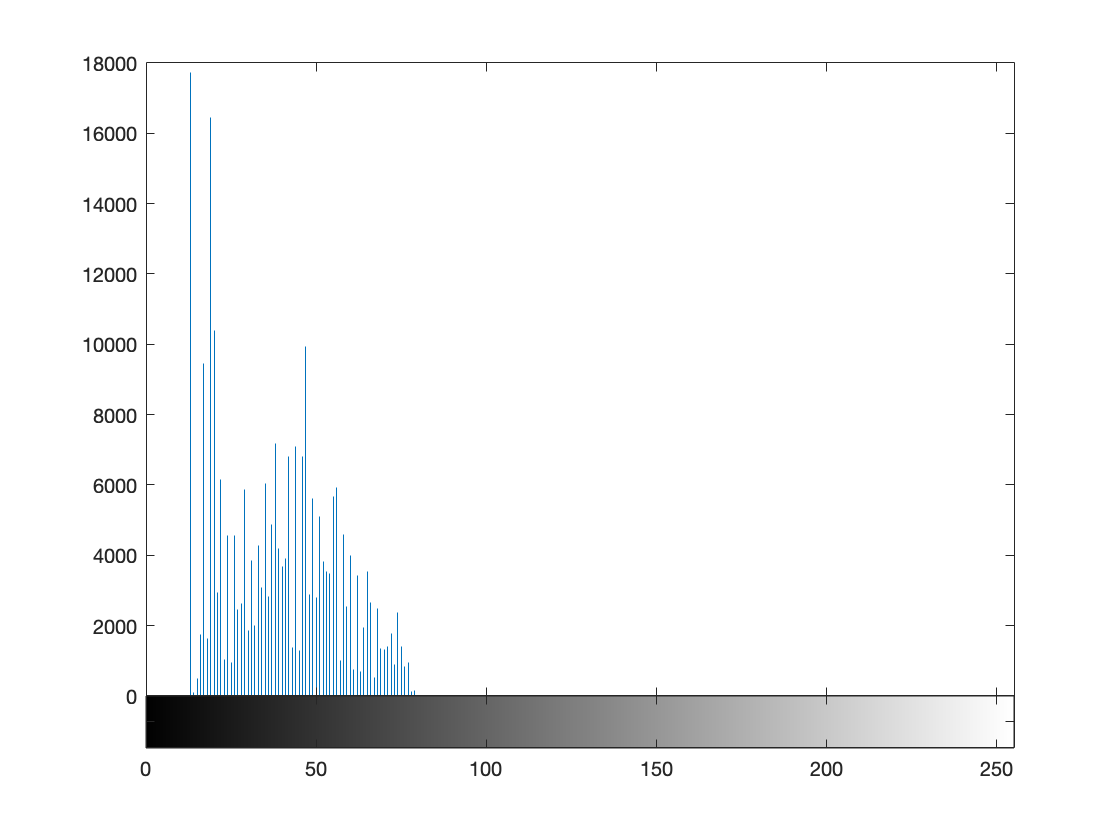

figure, imhist(f)
ylim('auto')

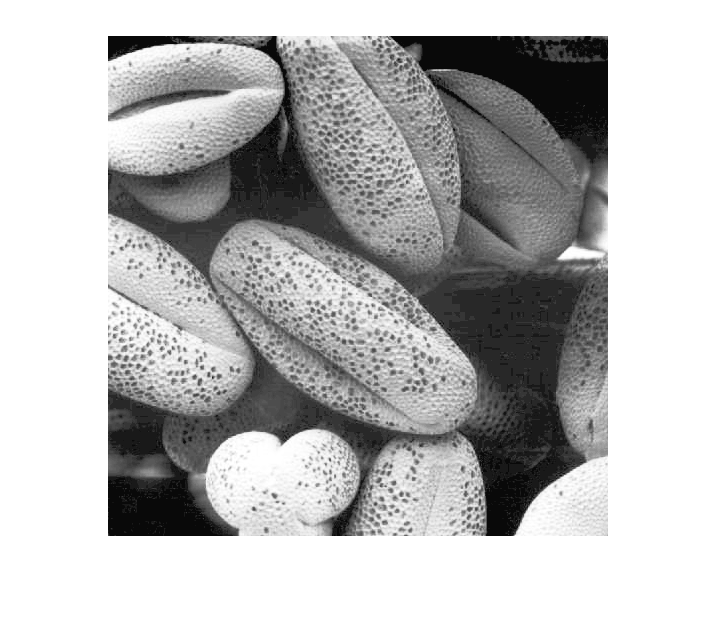

g = histeq(f, 256);
figure, imshow(g)

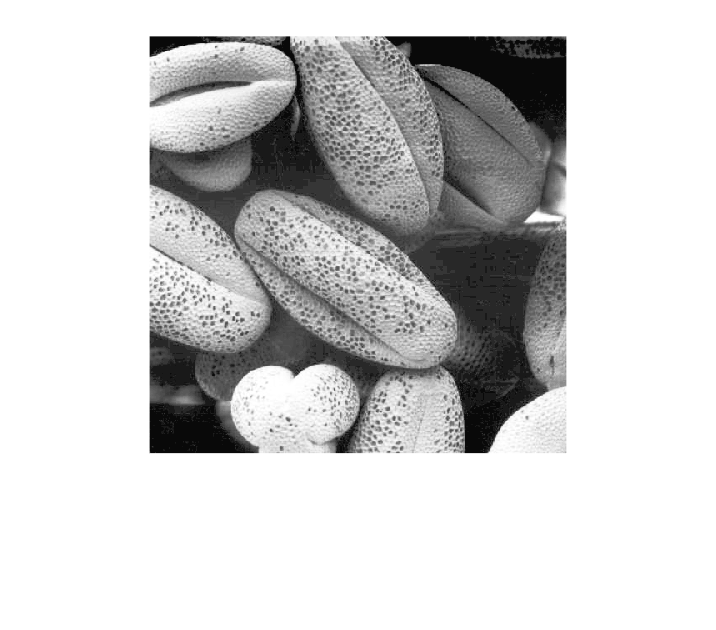

figure, imshow(g)
ylim('auto')

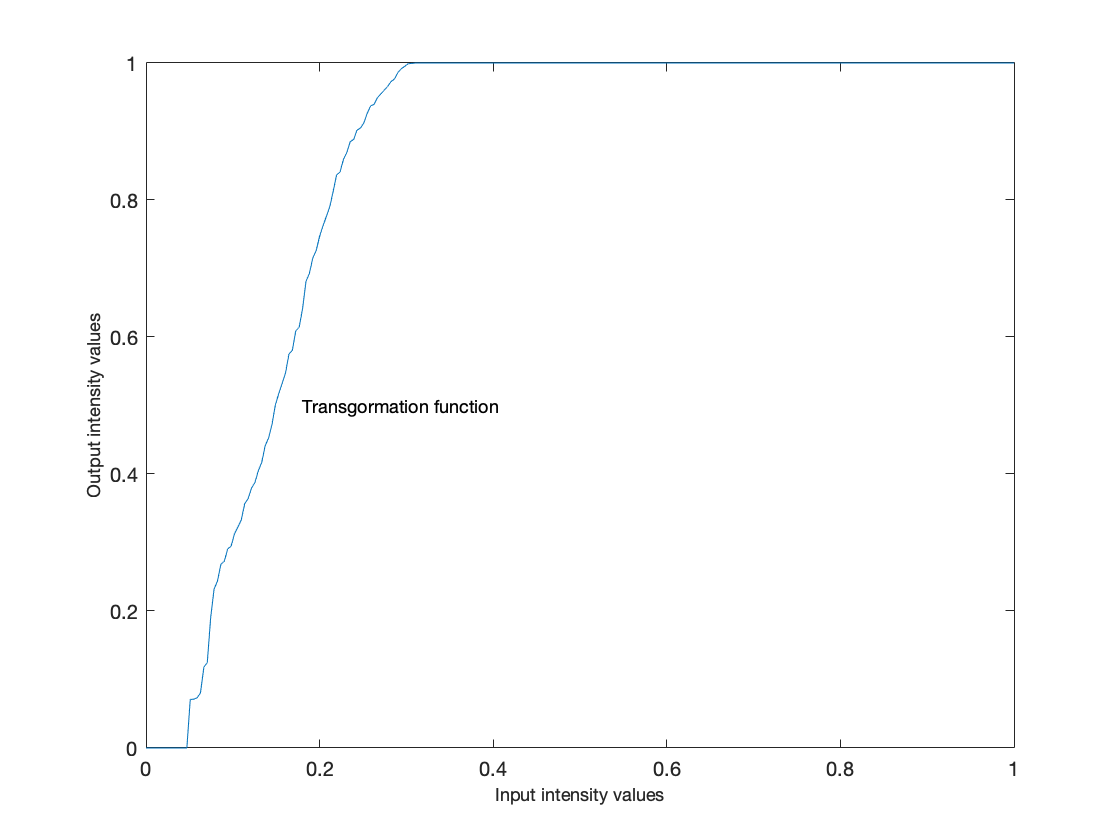


hnorm = imhist(f)./numel(f);
cdf = cumsum(hnorm);
x = linspace(0, 1, 256);
figure, plot(x, cdf)
axis([0 1 0 1])
set(gca, 'xtick', 0:0.2:1)
set(gca, 'ytick', 0:0.2:1)
xlabel('Input intensity values', 'fontsize', 9)
ylabel('Output intensity values', 'fontsize', 9)
text(0.18, 0.5, 'Transgormation function', 'fontsize', 9)

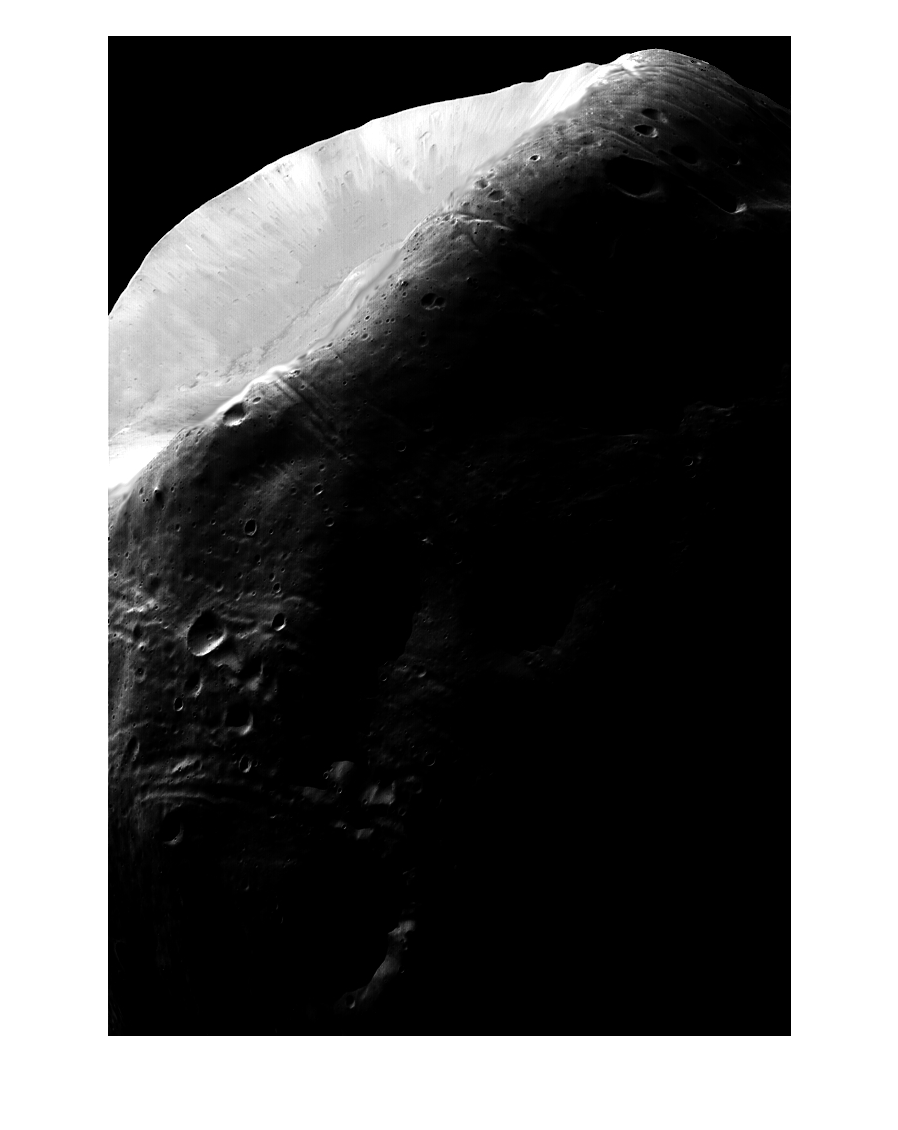

f = imread('Moonphobos.tif');
imshow(f)

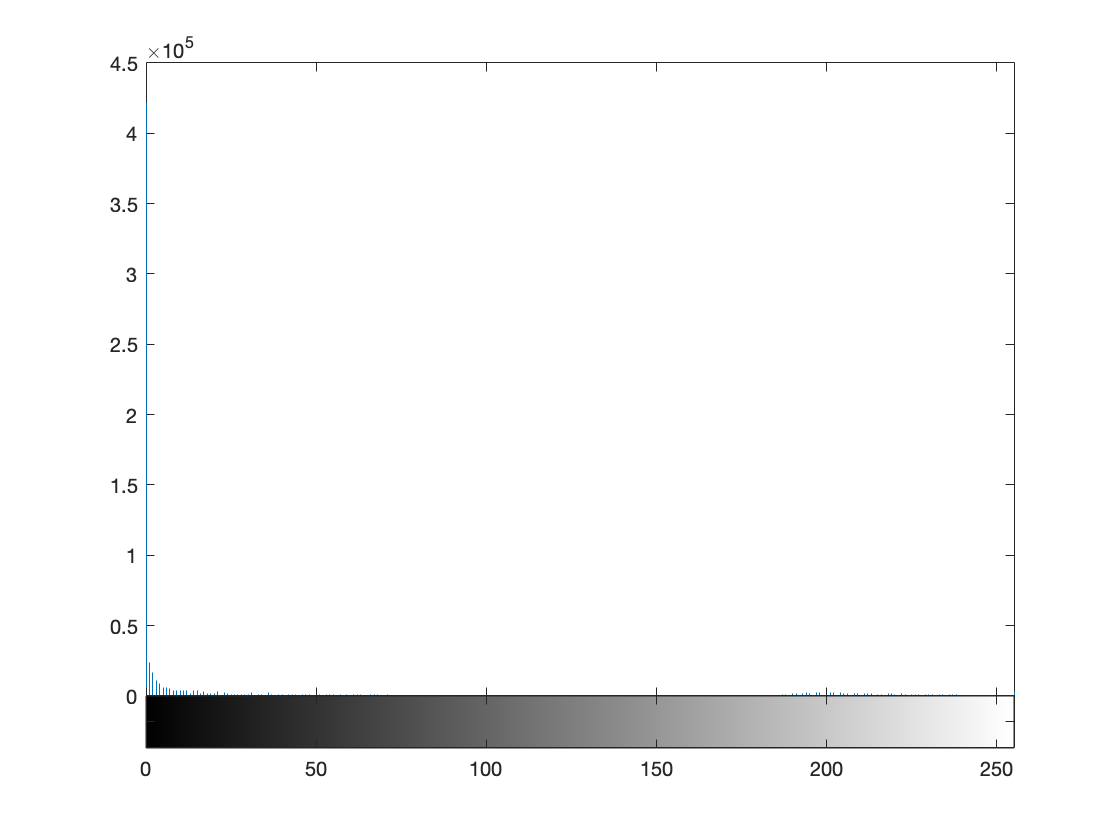

figure, imhist(f)
ylim('auto')

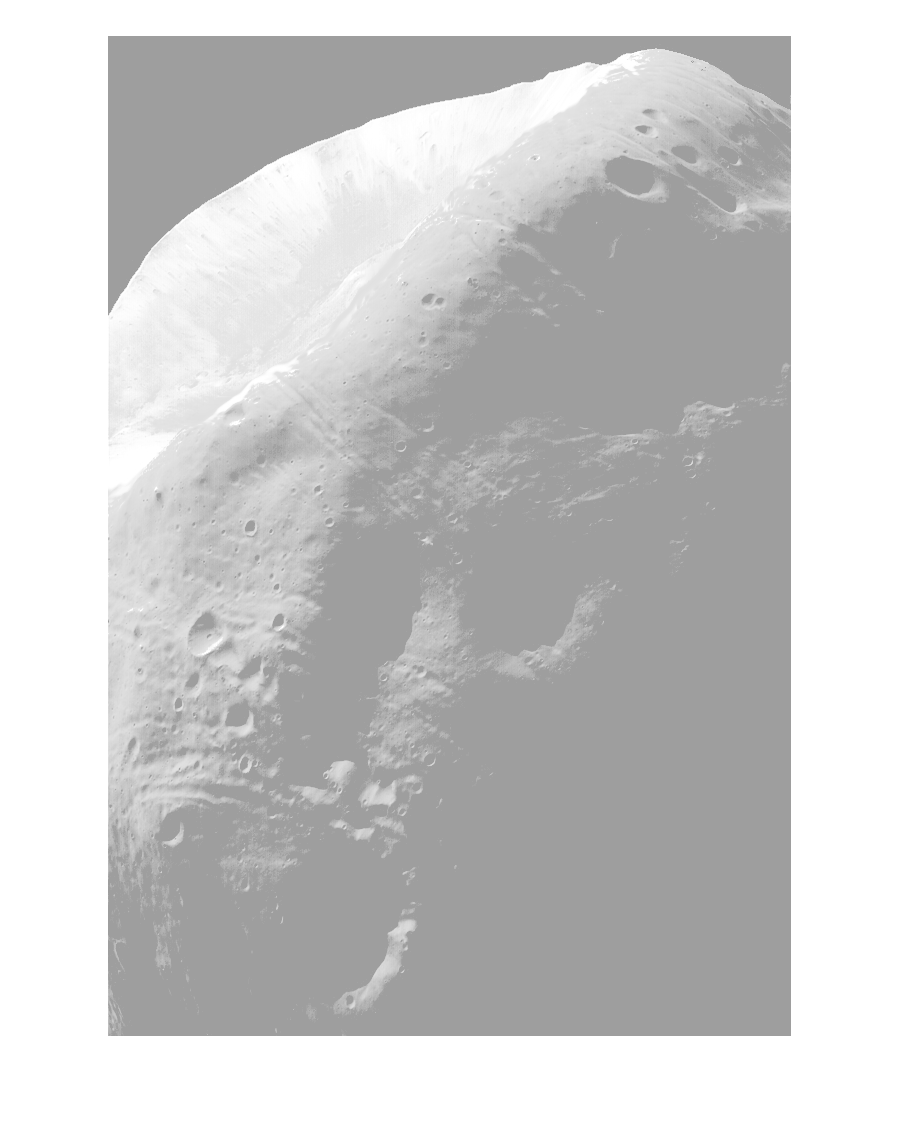

g = histeq(f, 256);
figure, imshow(g)

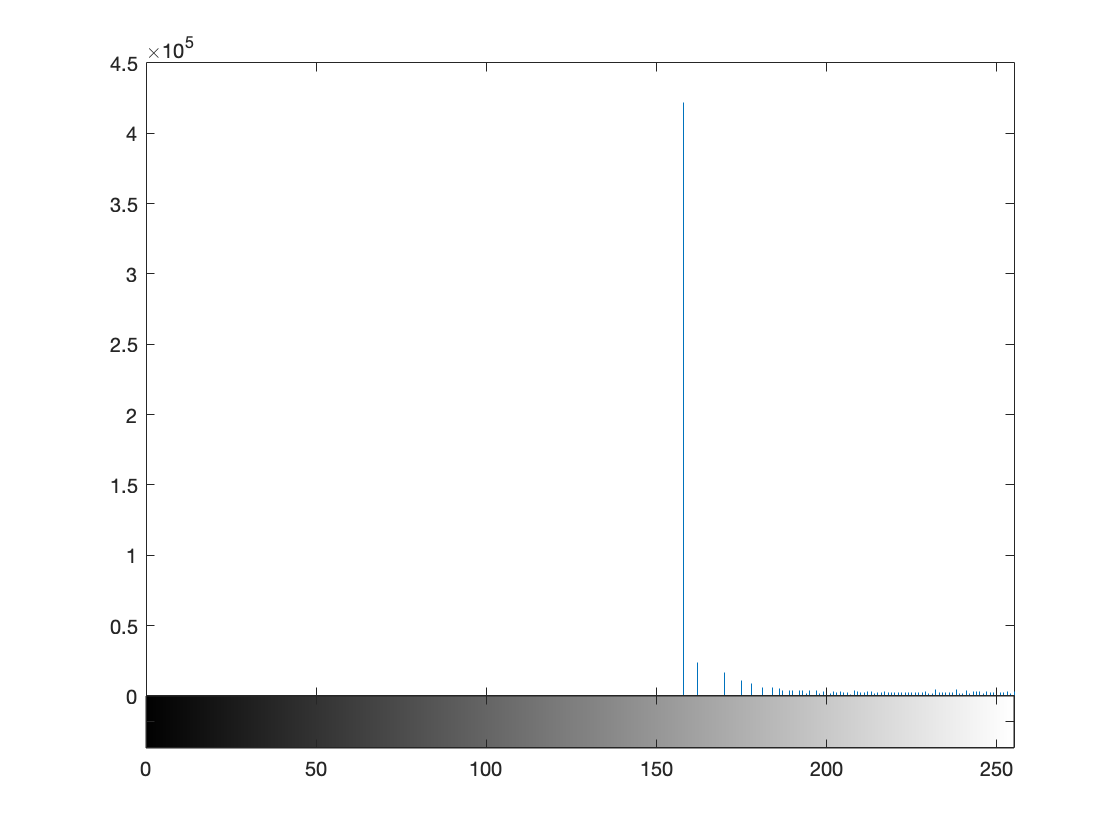

figure, imhist(g)
ylim('auto')


p = manualhist

Incorrect number of inputs.


p =     0.0019    0.0019    0.0020    0.0020    0.0021    0.0022    0.0024    0.0025    0.0027    0.0029    0.0031    0.0034    0.0037    0.0040    0.0044    0.0048    0.0053    0.0058    0.0064    0.0070    0.0077    0.0084    0.0091    0.0099    0.0106    0.0114    0.0122    0.0130    0.0138    0.0145    0.0152    0.0159    0.0165    0.0170    0.0175    0.0179    0.0181    0.0183    0.0184    0.0184    0.0182    0.0180    0.0177    0.0173    0.0168    0.0162    0.0156    0.0149    0.0142    0.0134


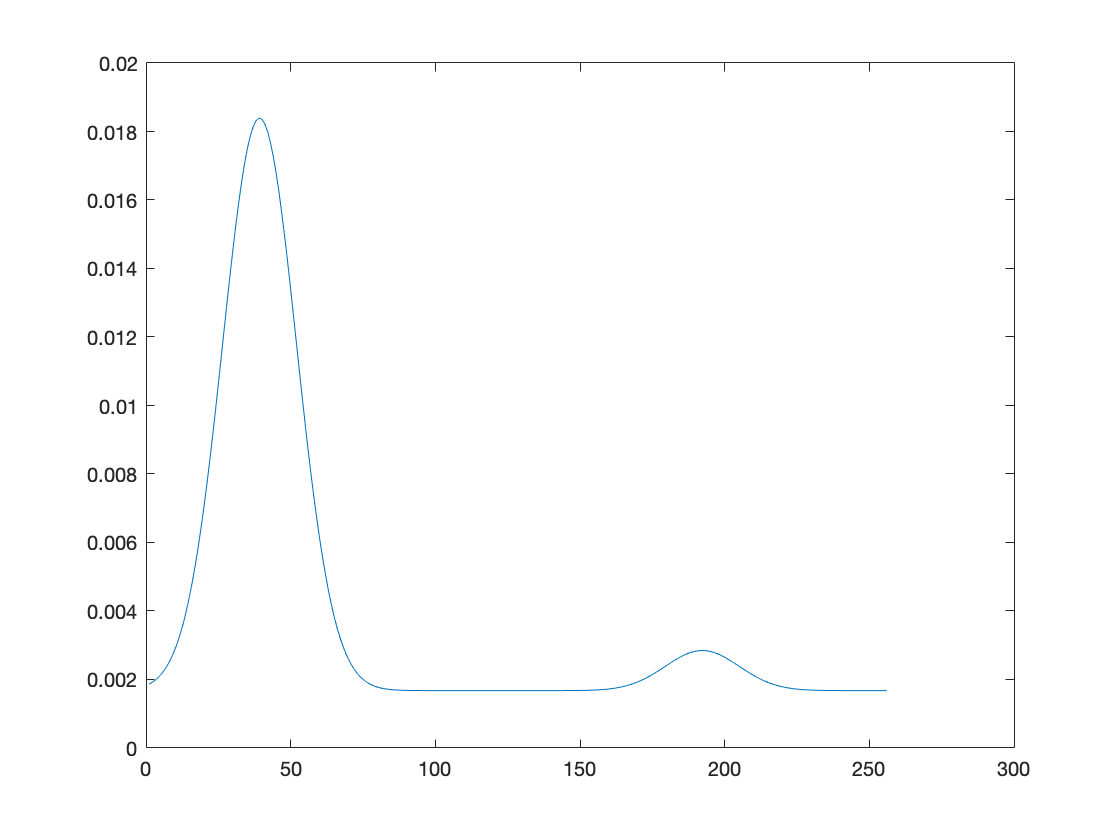

plot(1:256, p);

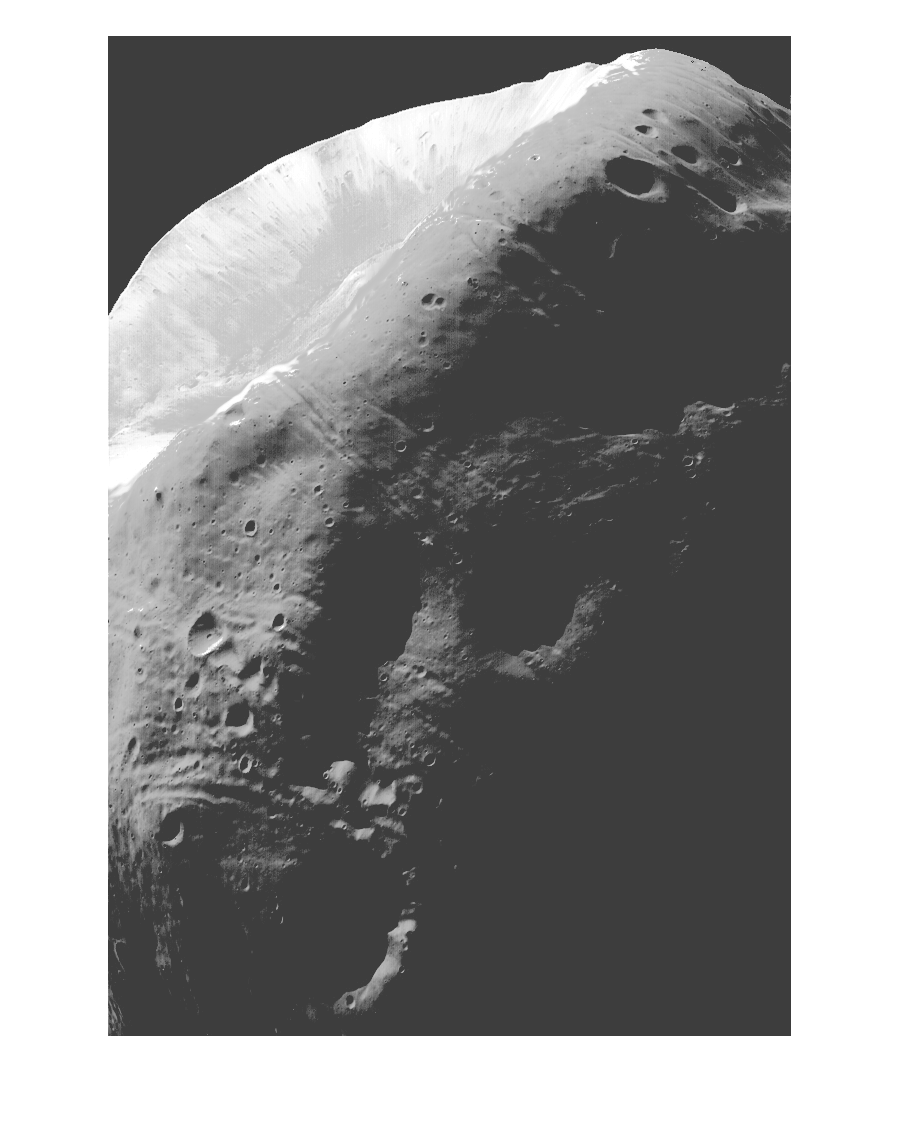

g1 = histeq(f, p);
figure, imshow(g1);